**Tasmanian Devil Facial Tumor Disease Simulation**

This simulation aims to inform the populace of the danger that Devil Facial Tumor Disease (DFTD) has on the Tasmanian Devil population. DFTD is a transmissable cancer that takes the form of lumps of soft tissue around the mouth. DFTD is most often trasmitted by bites, when the teeth come into contact with the cancer tissue. Other ways of transmission include ingesting infected carcasses and sharing food.

**Model Details**

This model utilises random walks and cellular automata to simulate the movement of the tasmanian devil population and the spread of the disease throughout it. The movement is governed by a 2-dimensional random walk that has dynamic weighting dictacted by the use of cellular automata. For any given cell (tasmanian devil), the weighting of the movement is adjusted based on the neighours surrounding it. This weighting will increase the chance for the cell to either move closer or further away from their neighbours depending on the time of year to reflect the change in behaviour during mating seasons.

Cellular autmomata is utilised to determine disease transmission and procreation during mating season. For any uninfected cells, the chance that they are infected in the next iteration of the simulation is determined by the number of surrounding infected cells. The chance of infection is 12% multiplied by the number of infected neighbours. If there are no surrounding infected cells, there is a 5% chance that the cell can gain a 12% chance to be infected.

**Results**

This script produces 2 visible outputs. The first is a written output outlying the week the simulation is currently in, the living population, and the percentage that are infected. The second output is a video file that shows the movement and change in population throughout the simulation.

With the current settings there will be an initial population of around 300-400 with an infected percentage of around 33%. The population will increase between weeks 8 and 20 of each year to simulate breeding season. Afterwards, the population will decrease as the disease kills the infected population.

%       N - Amount of iterations sim will run for.
%           if N = 1 then simulation runs for 1 week (dt = 1 week)
%       init_pos - Initial positions of every Tasmainian devil in sim, can
%                   use rand function to uniformally distribute tasmaninian
%                   devils over matrix  
A = 300; % size of sim
B = 400; % size of sim
N = 104; % two years
infected_percentage = .2;
sd  = 0.45; 
init_pos = rand(A,B)>0.998;
init_pos = init_pos + abs(2*(rand(A,B)>0.999));
infected = sum(sum(init_pos > 1));
pop = sum(sum(init_pos == 1));


Week 2 - Living: 374, Infected: 32.89%
Week 3 - Living: 374, Infected: 34.22%
Week 4 - Living: 374, Infected: 35.83%
Week 5 - Living: 374, Infected: 35.83%
Week 6 - Living: 374, Infected: 36.36%
Week 7 - Living: 374, Infected: 36.36%
Week 8 - Living: 383, Infected: 36.29%
Week 9 - Living: 389, Infected: 36.76%
Week 10 - Living: 397, Infected: 37.03%
Week 11 - Living: 402, Infected: 38.31%
Week 12 - Living: 417, Infected: 37.41%
Week 13 - Living: 433, Infected: 36.49%
Week 14 - Living: 451, Infected: 37.03%
Week 15 - Living: 466, Infected: 38.20%
Week 16 - Living: 481, Infected: 38.67%
Week 17 - Living: 509, Infected: 37.33%
Week 18 - Living: 557, Infected: 35.91%
Week 19 - Living: 585, Infected: 35.38%
Week 20 - Living: 619, Infected: 35.38%
Week 21 - Living: 619, Infected: 37.64%
Week 22 - Living: 619, Infected: 39.90%
Week 23 - Living: 619, Infected: 41.36%
Week 24 - Living: 619, Infected: 42.49%
Week 25 - Living: 619, Infected: 44.91%
Week 26 - Living: 619, Infected: 46.04%
Week 27 

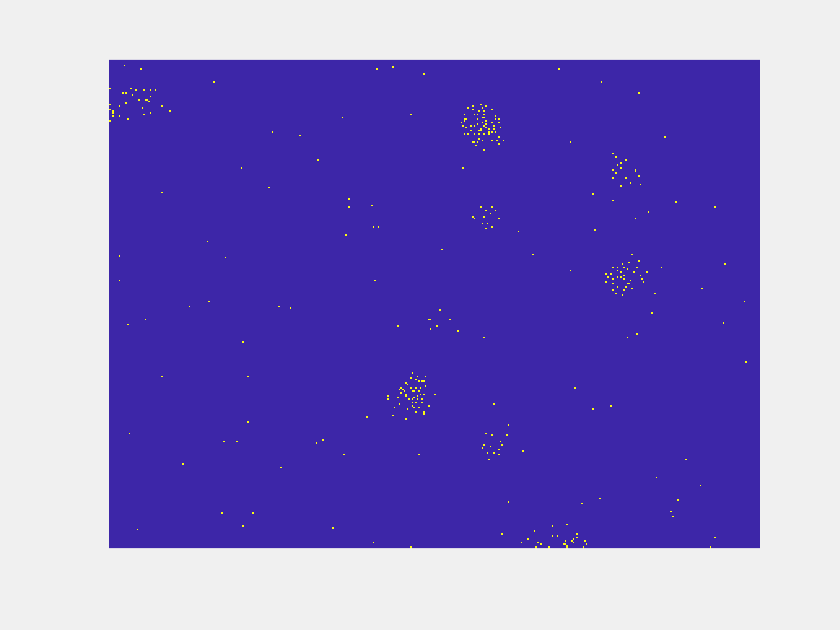


[positions,population,infection_percentage] = Tasmianian_Devil_sim(N, init_pos);

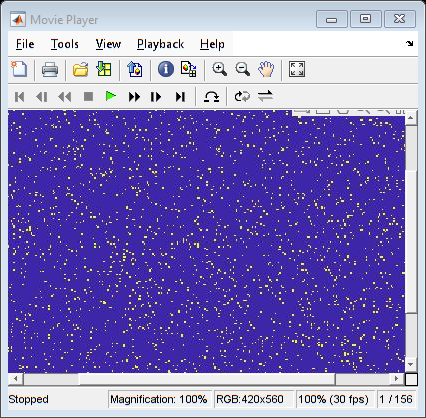

implay Simulation_vid.avi